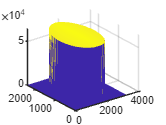

zbuf = imread('C:\Users\Max Cooper\Documents\pathcam\build\mask.png');
%zbuf2 = imread('C:\Users\Max Cooper\Documents\pathcam\build\img.png');
%k = plotSection(zbuf2);
surf(zbuf(1:2:end,1:2:end),'EdgeColor','none')

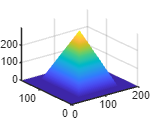


rows = 800;
cols = 1000;
radius = 300;
pyr = zeros(rows,cols);
for i = 0:radius
    for j = 0:radius
        y = cols/2-radius+i;
        x = rows/2-radius+j;
        if(j<i)
            pyr(x,y) = j;
            pyr(rows - x,y) = j;
            pyr(rows - x,cols - y) = j;
            pyr(x,cols - y) = j;
        else
            pyr(x,y) = i;
            pyr(rows - x,y)=i;
            pyr(rows - x,cols - y) = i;
            pyr(x,cols - y) = i;
        end
    end
end

surf(pyr(1:5:end,1:5:end),'EdgeColor','none')

function k = plotSection(k)
coneplot = imread('C:\Users\Max Cooper\Documents\pathcam\build\mask.png');
coneplot(coneplot<k) = 0;
stats = regionprops(coneplot,'BoundingBox');
bb = stats.BoundingBox;
k = coneplot(ceil(bb(2)):bb(4)+ceil(bb(2)),ceil(bb(1)):bb(3)+ceil(bb(1)));
%surf(k(1:2:end,1:2:end),'EdgeColor','none')
end